%Modulo y fase
% a)
hbut = freqz(NumButt,DenButt,5000)

hbut =    1.0000 + 0.0000i
   1.0000 - 0.0025i
   1.0000 - 0.0050i
   1.0000 - 0.0074i
   1.0000 - 0.0099i
   0.9999 - 0.0124i
   0.9999 - 0.0149i
   0.9998 - 0.0173i
   0.9998 - 0.0198i
   0.9998 - 0.0223i


hcheb1 = freqz(NumCheb1,DenCheb1,5000)

hcheb1 =    0.9886 + 0.0000i
   0.9885 - 0.0030i
   0.9885 - 0.0060i
   0.9885 - 0.0090i
   0.9885 - 0.0120i
   0.9884 - 0.0151i
   0.9884 - 0.0181i
   0.9883 - 0.0211i
   0.9883 - 0.0241i
   0.9882 - 0.0271i


hcheb2 = freqz(NumCheb2,DenCheb2,5000)

hcheb2 =    1.0000 + 0.0000i
   1.0000 - 0.0046i
   1.0000 - 0.0092i
   0.9999 - 0.0139i
   0.9998 - 0.0185i
   0.9997 - 0.0231i
   0.9996 - 0.0277i
   0.9995 - 0.0323i
   0.9993 - 0.0370i
   0.9991 - 0.0416i


hellip = freqz(NumEllip,DenEllip,5000)

hellip =    0.9886 + 0.0000i
   0.9885 - 0.0026i
   0.9885 - 0.0051i
   0.9885 - 0.0077i
   0.9885 - 0.0102i
   0.9885 - 0.0128i
   0.9884 - 0.0153i
   0.9884 - 0.0179i
   0.9884 - 0.0204i
   0.9883 - 0.0230i


fbut = linspace(0,Fs/2,length(hbut))

fbut = 	1.0e+04 *

         0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0064    0.0069    0.0074    0.0079    0.0084    0.0089    0.0094    0.0099    0.0104    0.0109    0.0114    0.0119    0.0124    0.0129    0.0134    0.0139    0.0144    0.0149    0.0154    0.0159    0.0164    0.0169    0.0174    0.0179    0.0184    0.0189    0.0193    0.0198    0.0203    0.0208    0.0213    0.0218    0.0223    0.0228    0.0233    0.0238    0.0243


fcheb1 = linspace(0,Fs/2,length(hcheb1))

fcheb1 = 	1.0e+04 *

         0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0064    0.0069    0.0074    0.0079    0.0084    0.0089    0.0094    0.0099    0.0104    0.0109    0.0114    0.0119    0.0124    0.0129    0.0134    0.0139    0.0144    0.0149    0.0154    0.0159    0.0164    0.0169    0.0174    0.0179    0.0184    0.0189    0.0193    0.0198    0.0203    0.0208    0.0213    0.0218    0.0223    0.0228    0.0233    0.0238    0.0243


fcheb2 = linspace(0,Fs/2,length(hcheb2))

fcheb2 = 	1.0e+04 *

         0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0064    0.0069    0.0074    0.0079    0.0084    0.0089    0.0094    0.0099    0.0104    0.0109    0.0114    0.0119    0.0124    0.0129    0.0134    0.0139    0.0144    0.0149    0.0154    0.0159    0.0164    0.0169    0.0174    0.0179    0.0184    0.0189    0.0193    0.0198    0.0203    0.0208    0.0213    0.0218    0.0223    0.0228    0.0233    0.0238    0.0243


fellip = linspace(0,Fs/2,length(hellip))

fellip = 	1.0e+04 *

         0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0064    0.0069    0.0074    0.0079    0.0084    0.0089    0.0094    0.0099    0.0104    0.0109    0.0114    0.0119    0.0124    0.0129    0.0134    0.0139    0.0144    0.0149    0.0154    0.0159    0.0164    0.0169    0.0174    0.0179    0.0184    0.0189    0.0193    0.0198    0.0203    0.0208    0.0213    0.0218    0.0223    0.0228    0.0233    0.0238    0.0243


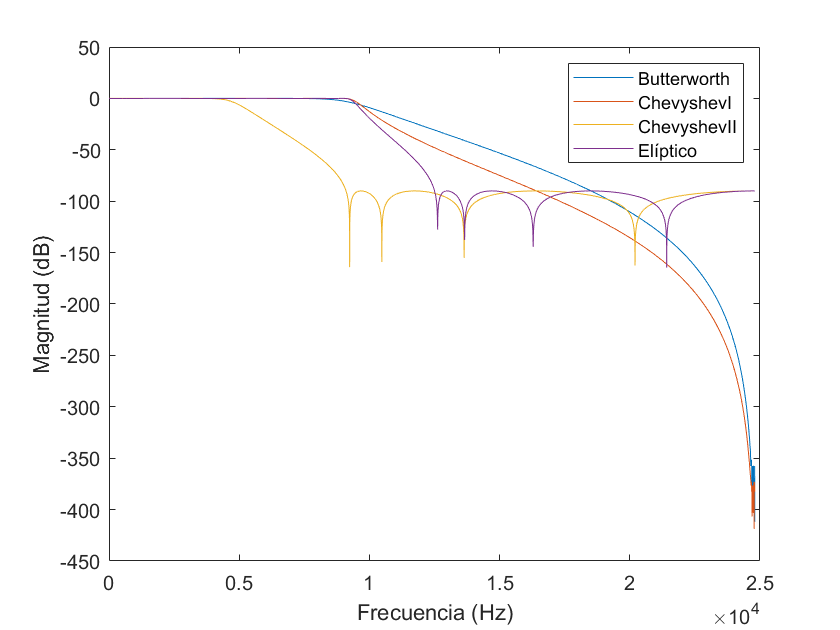


plot(fbut,20*log10(abs(hbut)))
hold on
plot(fcheb1,20*log10(abs(hcheb1)))
plot(fcheb2,20*log10(abs(hcheb2)))
plot(fellip,20*log10(abs(hellip)))
xlabel('Frecuencia (Hz)')
ylabel('Magnitud (dB)')
legend('Butterworth','ChevyshevI','ChevyshevII','Elíptico')
hold off


%b)
hold off

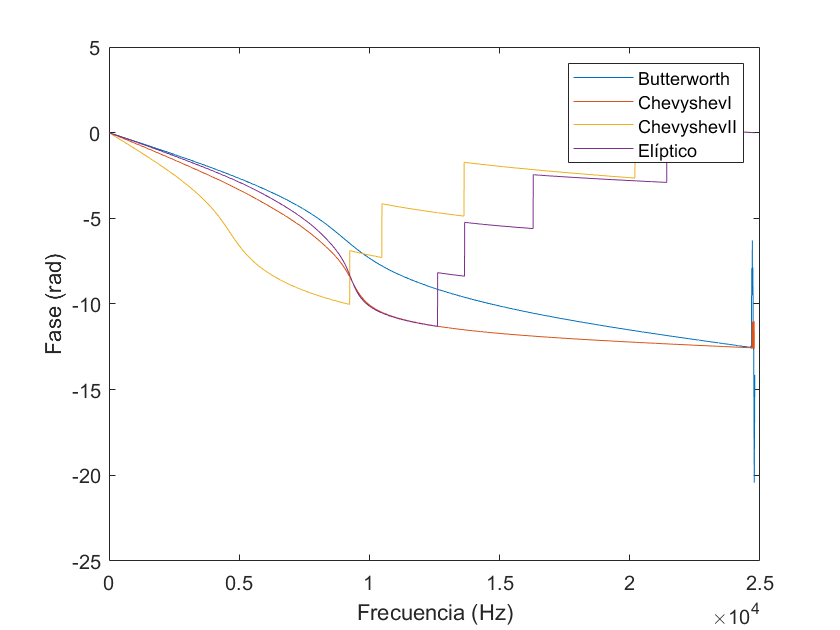

plot(fbut,unwrap(angle(hbut)))
hold on
plot(fcheb1,unwrap(angle(hcheb1)))
plot(fcheb2,unwrap(angle(hcheb2)))
plot(fellip,unwrap(angle(hellip)))
xlabel('Frecuencia (Hz)')
ylabel('Fase (rad)')
legend('Butterworth','ChevyshevI','ChevyshevII','Elíptico')
%La fase sera no lineal cuando tu señal de entrada afecta diferente a cada
%componente de frecuencia


%Polos y ceros
%a)
hold off

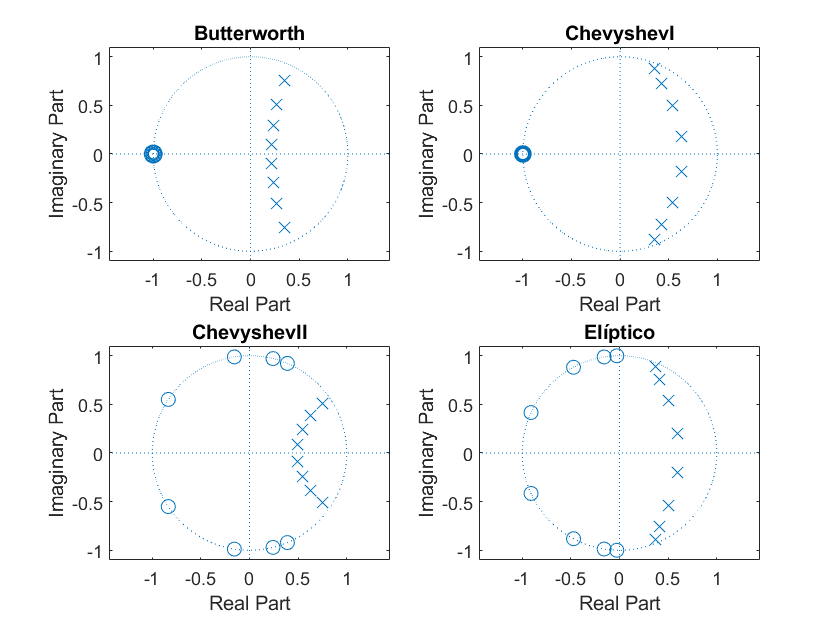

figure
subplot(2,2,1)
zplane(roots(NumButt),roots(DenButt))
title('Butterworth')
subplot(2,2,2)
zplane(roots(NumCheb1),roots(DenCheb1))
title('ChevyshevI')
subplot(2,2,3)
zplane(roots(NumCheb2),roots(DenCheb2))
title('ChevyshevII')
subplot(2,2,4)
zplane(roots(NumEllip),roots(DenEllip))
title('Elíptico')
hold off

%Como todas las equis (polos) están dentro de la circunferencia
%quiere decir que es un sistema estable, si sale una solo
%ya se vuelve inestable

%e) Banda de paso que corresponde con los polos
dend = roots(DenEllip)

dend =    0.3682 + 0.8847i
   0.3682 - 0.8847i
   0.4111 + 0.7596i
   0.4111 - 0.7596i
   0.5044 + 0.5425i
   0.5044 - 0.5425i
   0.5913 + 0.2025i
   0.5913 - 0.2025i


fd= angle(dend).*(1/(2*pi))*Fs

fd = 	1.0e+03 *

    9.2865
   -9.2865
    8.4841
   -8.4841
    6.4868
   -6.4868
    2.6043
   -2.6043


%tenemos par conjugado, en una raiz tenemos un par positivo y negativo,
%solo nos interesan los positivos
fposd=find(fd>0) % me da el indice

fposd =      1
     3
     5
     7


for i=1:length(fposd)
    fposd2(i) = fd(fposd(i))
end

fposd2 = 	1.0e+03 *

    9.2865    8.4841    6.4868    2.6043


fposd2 = 	1.0e+03 *

    9.2865    8.4841    6.4868    2.6043


fposd2 = 	1.0e+03 *

    9.2865    8.4841    6.4868    2.6043


fposd2 = 	1.0e+03 *

    9.2865    8.4841    6.4868    2.6043



%e) Banda eliminada es banda atenuada que corresponde con los zeros
nume = roots(NumEllip)

nume =   -0.9093 + 0.4160i
  -0.9093 - 0.4160i
  -0.4727 + 0.8812i
  -0.4727 - 0.8812i
  -0.0274 + 0.9996i
  -0.0274 - 0.9996i
  -0.1580 + 0.9874i
  -0.1580 - 0.9874i


fe= angle(nume).*(1/(2*pi))*Fs

fe = 	1.0e+04 *

    2.1413
   -2.1413
    1.6286
   -1.6286
    1.2616
   -1.2616
    1.3653
   -1.3653


%tenemos par conjugado, en una raiz tenemos un par positivo y negativo,
%solo nos interesan los positivos
fpose=find(fe>0) % me da el indice

fpose =      1
     3
     5
     7


for i=1:length(fpose)
    fpose2(i) = fe(fpose(i))
end

fpose2 = 	1.0e+04 *

    2.1413    1.6286    1.2616    1.3653


fpose2 = 	1.0e+04 *

    2.1413    1.6286    1.2616    1.3653


fpose2 = 	1.0e+04 *

    2.1413    1.6286    1.2616    1.3653


fpose2 = 	1.0e+04 *

    2.1413    1.6286    1.2616    1.3653


%Estabilidad
%La estabilidad la determinan los polos
%a)
denominador = poly(0.95*dend)

denominador =     1.0000   -3.5624    7.0550   -9.1257    8.3259   -5.4031    2.4309   -0.6940    0.0974


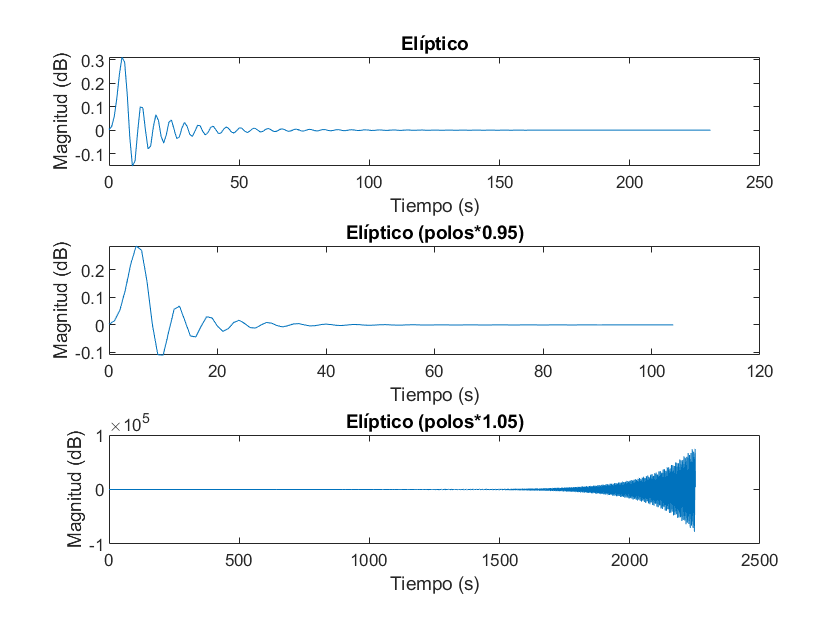


hold off


figure
zplane(roots(NumEllip),roots(denominador), {'o', '*'})
hold on
zplane(roots(NumEllip),roots(DenEllip), {'o', 'x'})
title('Elíptico')
xlim([-1.5 1.5])


%b)
hellip_95 = freqz(NumEllip,denominador,5000)

hellip_95 =    0.9785 + 0.0000i
   0.9785 - 0.0026i
   0.9785 - 0.0053i
   0.9785 - 0.0079i
   0.9784 - 0.0105i
   0.9784 - 0.0132i
   0.9784 - 0.0158i
   0.9783 - 0.0184i
   0.9783 - 0.0211i
   0.9782 - 0.0237i




%c)
denominador105 = poly(1.05*dend)

denominador105 =     1.0000   -3.9374    8.6185  -12.3216   12.4249   -8.9120    4.4317   -1.3984    0.2169


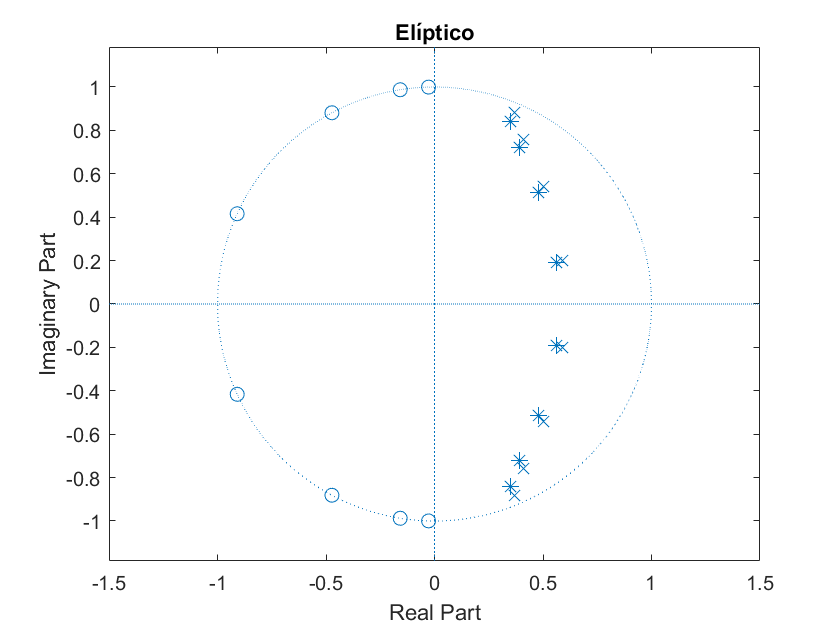


hold off


figure
zplane(roots(NumEllip),roots(denominador105), {'o', '*'})
hold on
zplane(roots(NumEllip),roots(DenEllip), {'o', 'x'})
title('Elíptico')
xlim([-1.5 1.5])

%d)
hellip_105 = freqz(NumEllip,denominador105,5000)

hellip_105 =    0.9892 + 0.0000i
   0.9892 - 0.0024i
   0.9892 - 0.0049i
   0.9892 - 0.0073i
   0.9892 - 0.0097i
   0.9891 - 0.0122i
   0.9891 - 0.0146i
   0.9891 - 0.0170i
   0.9890 - 0.0195i
   0.9890 - 0.0219i


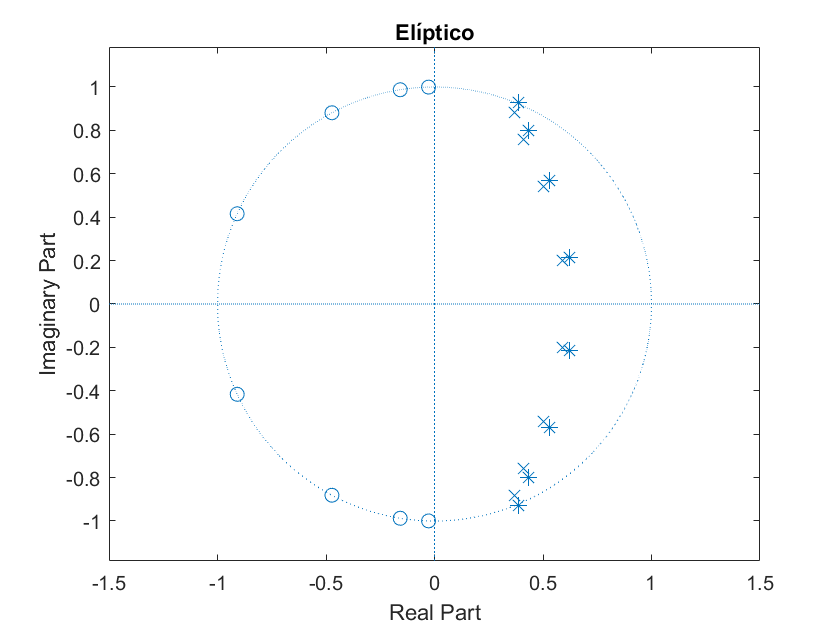




%e)
hold off

%
fellip = linspace(0,Fs/2,length(hellip_95))

fellip = 	1.0e+04 *

         0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0064    0.0069    0.0074    0.0079    0.0084    0.0089    0.0094    0.0099    0.0104    0.0109    0.0114    0.0119    0.0124    0.0129    0.0134    0.0139    0.0144    0.0149    0.0154    0.0159    0.0164    0.0169    0.0174    0.0179    0.0184    0.0189    0.0193    0.0198    0.0203    0.0208    0.0213    0.0218    0.0223    0.0228    0.0233    0.0238    0.0243


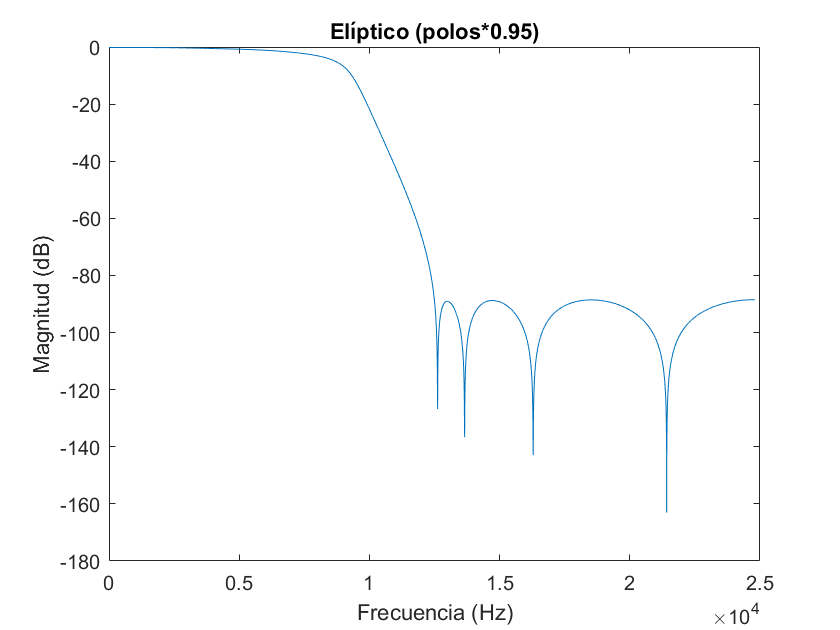

plot(fellip,20*log10(abs(hellip_95)))
xlabel('Frecuencia (Hz)')
ylabel('Magnitud (dB)')
title('Elíptico (polos*0.95)')


hold off

fellip = linspace(0,Fs/2,length(hellip_105))

fellip = 	1.0e+04 *

         0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0064    0.0069    0.0074    0.0079    0.0084    0.0089    0.0094    0.0099    0.0104    0.0109    0.0114    0.0119    0.0124    0.0129    0.0134    0.0139    0.0144    0.0149    0.0154    0.0159    0.0164    0.0169    0.0174    0.0179    0.0184    0.0189    0.0193    0.0198    0.0203    0.0208    0.0213    0.0218    0.0223    0.0228    0.0233    0.0238    0.0243


plot(fellip,20*log10(abs(hellip_105)))
xlabel('Frecuencia (Hz)')
ylabel('Magnitud (dB)')
title('Elíptico (polos*1.05)')

%f)Los polos se desplazan por el factor multilpicado
%g)Lo mismo, desplaza los polos pero los ceros no se tocan
%h)
[h, t] = impz(NumEllip, DenEllip)

h =     0.0023
    0.0156
    0.0561
    0.1354
    0.2382
    0.3112
    0.2893
    0.1529
   -0.0330
   -0.1524


t =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


[h_95, t_95] = impz(NumEllip, denominador)

h_95 =     0.0023
    0.0152
    0.0534
    0.1266
    0.2203
    0.2873
    0.2722
    0.1591
    0.0011
   -0.1087


t_95 =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


[h_105, t_105] = impz(NumEllip, denominador105)

h_105 = 	1.0e+04 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000


t_105 =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


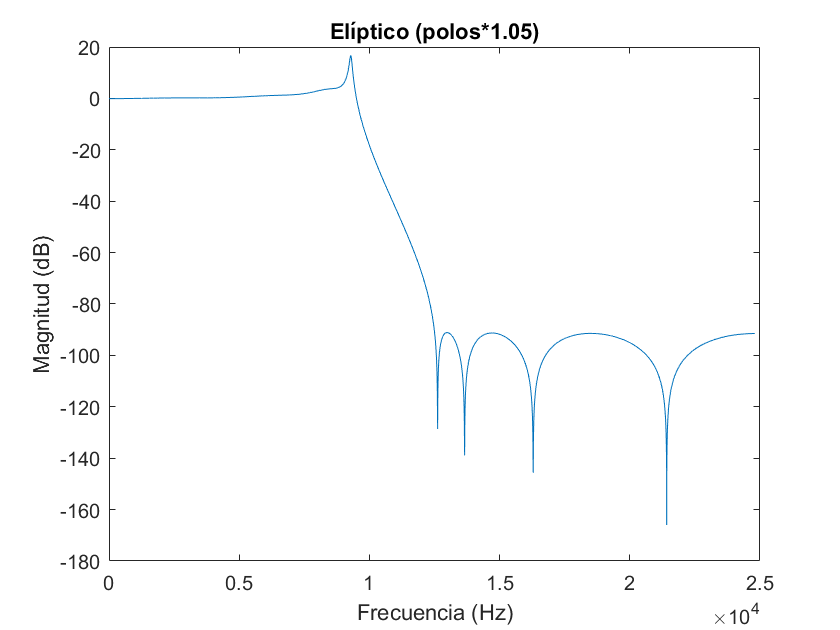


hold off

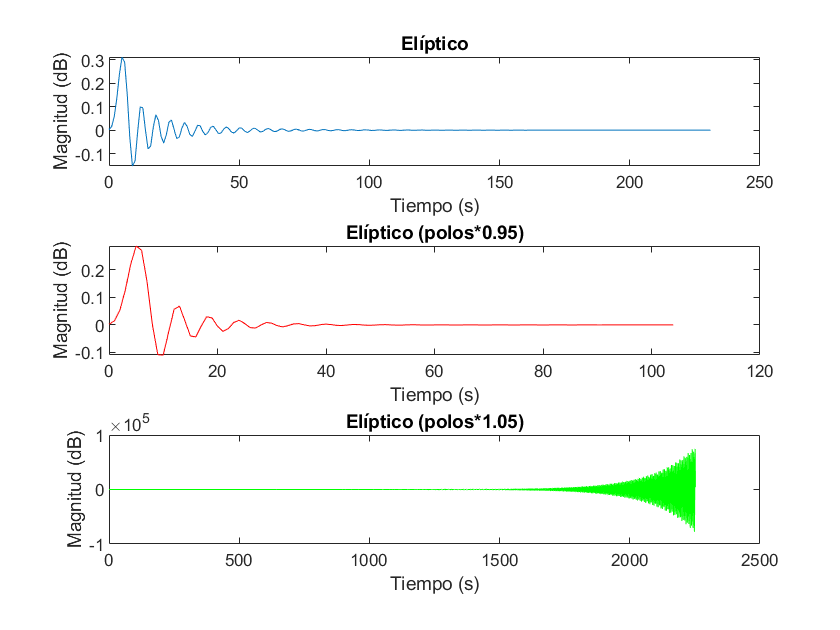

figure
subplot(3,1,1)
plot(t, h)
title('Elíptico')
xlabel('Tiempo (s)')
ylabel('Magnitud (dB)')
subplot(3,1,2)
plot(t_95, h_95, 'r')
title('Elíptico (polos*0.95)')
xlabel('Tiempo (s)')
ylabel('Magnitud (dB)')
subplot(3,1,3)
plot(t_105, h_105, 'g')
title('Elíptico (polos*1.05)')
xlabel('Tiempo (s)')
ylabel('Magnitud (dB)')